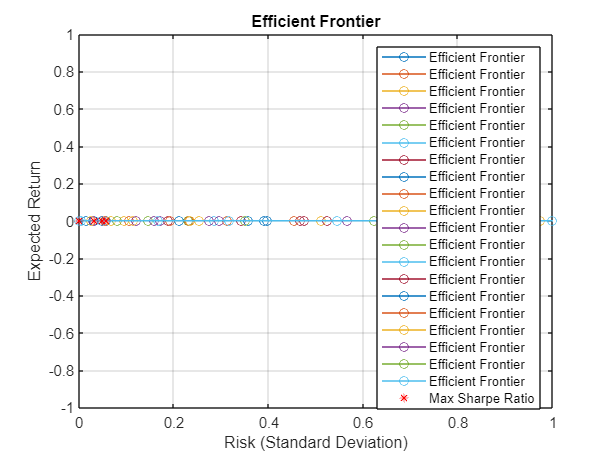

% Sample expected returns of assets
expectedReturns = expected_returns_10;

% Sample covariance matrix of asset returns
covarianceMatrix = cov_matrix_10;


%riskFreeRate = 0.00;


p = Portfolio('AssetMean', expectedReturns, 'AssetCovar', covarianceMatrix);


p = setDefaultConstraints(p);

% Estimate the efficient frontier
numPorts = 20; % Number of portfolios on the efficient frontier
[portfolioWeights, portfolioRisk, portfolioReturn] = estimateFrontier(p, numPorts);

% Calculate Sharpe ratios
sharpeRatios = (portfolioReturn - riskFreeRate) ./ portfolioRisk;

% Find the portfolio with the maximum Sharpe ratio
[maxSharpeRatio, maxSharpeIdx] = max(sharpeRatios);
maxSharpeWeights = portfolioWeights(:, maxSharpeIdx);
maxSharpeReturn = portfolioReturn(maxSharpeIdx);
maxSharpeRisk = portfolioRisk(maxSharpeIdx);

% Plot the efficient frontier
figure;
plot(portfolioRisk, portfolioReturn, 'o-', 'DisplayName', 'Efficient Frontier');
hold on;
plot(maxSharpeRisk, maxSharpeReturn, 'r*', 'DisplayName', 'Max Sharpe Ratio');
xlabel('Risk (Standard Deviation)');
ylabel('Expected Return');
title('Efficient Frontier');
legend('show');
grid on;


% Display the results for the portfolio with the maximum Sharpe ratio
disp('Optimal Portfolio Weights for Maximum Sharpe Ratio:');

Optimal Portfolio Weights for Maximum Sharpe Ratio:


disp(maxSharpeWeights);

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

disp('Optimal Portfolio Return for Maximum Sharpe Ratio:');

Optimal Portfolio Return for Maximum Sharpe Ratio:


disp(maxSharpeReturn);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



disp('Optimal Portfolio Risk for Maximum Sharpe Ratio:');

Optimal Portfolio Risk for Maximum Sharpe Ratio:


disp(maxSharpeRisk);

    0.0582    0.0484    0.0484    0.0484    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332         0         0         0



disp('Maximum Sharpe Ratio:');

Maximum Sharpe Ratio:


disp(maxSharpeRatio);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

